RMN_st.name='RMN'; 
RMN_st.lat=40.2783;
RMN_st.lon=-105.546;
RMN_st.alt=2760;
RMN_st.env='Mt';
RMN_st.footp='RB';

RMN_rd=read_betsy('RMN_head',RMN_st.name);
%test with all hourly values<0=NaN
RMNx_rd=read_betsy('RMN_head',RMN_st.name);

datevec(RMN_rd.Time(1))

ans =         2008           1           2           0           0           0

datevec(RMN_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(RMN_rd.U_S,[5 50 95])

ans =    21.3685   47.7050   87.6765

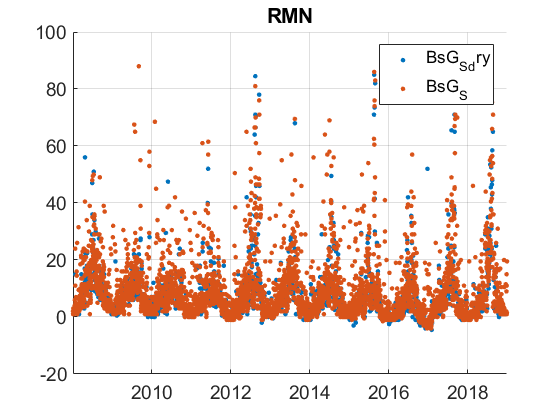

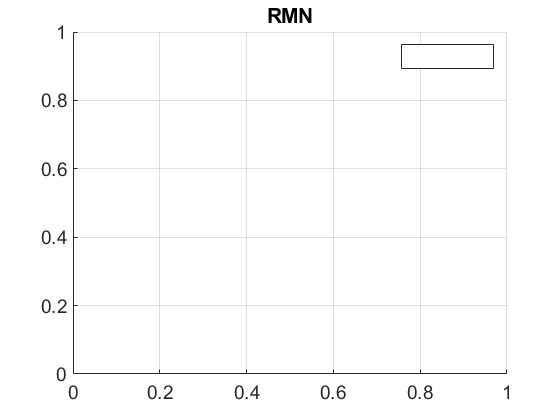

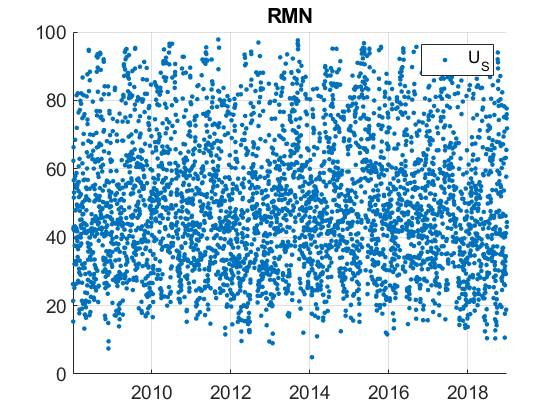

plotFigControl(RMN_rd,RMN_st.name);

% 1 size cut, ok
% sc: ok, max in summer, negatives i winter but not the first years



% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE3=[467;530;660]*ones(1,4);
% % lambdaAE7=[370 470 520 590 660 880 950];
% % RMN_cal=compute_exp_SSA(RMN_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(RMN_cal,RMN_st.name);

%Questions:
%problems:
% why is the amount of negatives during winter changing with time ? none from 2008 to 2011, increasing number of negatives from 2011 to 2016, no more in 2017 and 2018 
%jwith a clear rupture at the beginning of February 2017. Do you know what happened ? Can you correct it ?

RMN_tr=RMN_rd;
RMN_tr.y=year(RMN_tr.Time);
%eneleve une valeur de 2019
RMN_tr=RMN_tr(1:end-1,:);
% begin at the beginning of a year: 2008
% end: 2018
P=timerange('2008-01-01','2019-01-01');
RMN_tr=RMN_tr(P,:);

names=fieldnames(RMN_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    RMN_tr.(N{i})=[];
end

% dry= almost holes in winter!!

RMN_result= all_trend_STN(RMN_tr,RMN_st);


RMNx_tr=RMNx_rd;
RMNx_tr.y=year(RMNx_tr.Time);
%eneleve une valeur de 2019
RMNx_tr=RMNx_tr(1:end-1,:);
% begin at the beginning of a year: 2008
% end: 2018
P=timerange('2008-01-01','2019-01-01');
RMNx_tr=RMNx_tr(P,:);

names=fieldnames(RMNx_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    RMNx_tr.(N{i})=[];
end

% dry= almost holes in winter!!

RMNx_result= all_trend_STN(RMNx_tr,RMN_st);
% --> results with S11

RMN_result_D=RMNx_result;